% How do launch angle and initial speed affect the horizontal range, maximum height and flight time of a projectile?
% Intro 
% Projectile motion is when something gets launched in the air and moves with gravity pulling it down. It splits into horizontal and vertical parts.
% Doing this in MATLAB is very useful for engineers because they can use MATLAB to predict an object's motion before building or physically testing a system.

% My main question is how changing the launch angle and initial speed affects the horizontal range, maximum height and flight time of the projectile.

% Hypothesis

% I predict that, when initial speed and starting height remain constant, increasing the launch angle will increase maximum height and flight time. 
% The horizontal range should increase up to approximately 45° and then decrease. Complementary angles, such as 30° and 60°, should produce the same
% range under the assumptions of this model. Increasing initial speed should increase range, height and flight time.

% Assumptions 
% Gravity = 9.81 m/s²
% Air resistance is ignored
% Wind is ignored
% Ground is flat over the distance that will be travelled
% Projectile is treated as a single point 
% Horizontal acceleration = 0 (i.e., the horizontal speed of the object does not change)
% The projectile lands at the same height at which it was launched

% Horizontal motion

% x(t)=v0cos(θ)t

% x = horizontal position, metres
% v0=initial speed in m/s
% θ = launch angle
% t = time in seconds

% vertical motion 
% y(t) = h₀ + v₀ sin(θ)t − 0.5gt²

% y = vertical position, metres
% h0=starting height in metres
% v0= initial speed in m/s
% θ = launch angle
% g = gravitational acceleration, 9.81 m/s²
% t = time in seconds

% Initial Velocity Components

% vx = v₀ cos(θ)
% vy = v₀ sin(θ)

% The starting speed gets split into horizontal and vertical parts using basic trigonometry.
% As the launch angle increases, a greater proportion of the initial velocity acts vertically,
% while the horizontal component decreases.
% The launch angles are measured in degrees. Therefore, I will use MATLAB's sind() and cosd() 
% functions rather than sin() and cos(), because sind() and cosd() work directly with angles measured in degrees.



   % Test Conditions

% Initial speed = 20 m/s
% Starting height = 0 m
% Gravity = 9.81 m/s²
% Angles = 15°, 30°, 45°, 60°, 75°


% To make sure it is a fair test, I kept the starting speed, height, and gravity exactly the same for the first comparison. 
% Only the launch angle changes each time. This lets me see exactly how the angle affects the flight path without introducing
% other changing variables into the comparison.

% Test Conditions — Initial Speed Comparison

% To investigate the effect of initial speed, I will use:

% Launch angle = 45°
% Initial speeds = 10, 15, 20, 25 and 30 m/s
% Starting height = 0 m
% Gravitational acceleration = 9.81 m/s²

% Only the initial speed will change in this comparison. This allows me to investigate how changing the initial speed 
% affects the trajectory, maximum height, flight time and horizontal range.


% Manual Validation – 45° Example

% Horizontal velocity:

% vₓ = 20 × cos(45°) = 14.14 m/s

% Vertical velocity:

% vᵧ = 20 × sin(45°) = 14.14 m/s

% Maximum height:

% Maximum height = vᵧ² ÷ (2g)
% Maximum height = 14.14² ÷ (2 × 9.81) = 10.19 m

% Flight time:

% Flight time = 2vᵧ ÷ g
% Flight time = (2 × 14.14) ÷ 9.81 = 2.88 s

% Horizontal range:

% Horizontal range = vₓ × flight time = 40.77 m

% Note: The horizontal range was calculated using the unrounded
% values of vₓ and flight time.


% Basic Trajectory Calculation

% Initial conditions
v0 = 20;          % Initial speed (m/s)
angle = 45;       % Launch angle (degrees)
h0 = 0;           % Starting height (m)
g = 9.81;         % Gravitational acceleration (m/s^2)

% Initial velocity parts
vx = v0 * cosd(angle);
vy = v0 * sind(angle);

% Display velocity parts
fprintf('Horizontal velocity: %.2f m/s\n', vx);

Horizontal velocity: 14.14 m/s


fprintf('Vertical velocity: %.2f m/s\n', vy);

Vertical velocity: 14.14 m/s



% Create time values
t = 0:0.01:3;

% Horizontal position
x = v0 * cosd(angle) .* t;

% Vertical position
y = h0 + v0 * sind(angle) .* t - 0.5 * g .* t.^2;

% Display the first few position values
disp('First five horizontal positions:')

First five horizontal positions:


disp(x(1:5))

         0    0.1414    0.2828    0.4243    0.5657




disp('First five vertical positions:')

First five vertical positions:


disp(y(1:5))

         0    0.1409    0.2809    0.4198    0.5578



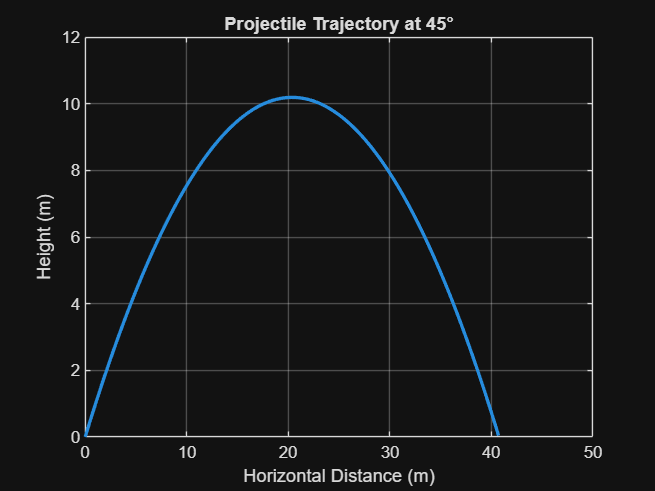


% Keep only points at or above ground level

valid = (y >= 0);

x_valid = x(valid);
y_valid = y(valid);

% Plot the trajectory

plot(x_valid, y_valid, 'LineWidth', 2)

grid on
title('Projectile Trajectory at 45°')
xlabel('Horizontal Distance (m)')
ylabel('Height (m)')



% Calculate time to maximum height

t_max_height = (v0 * sind(angle)) / g;

% Calculate maximum height

max_height = h0 + v0 * sind(angle) * t_max_height ...
    - 0.5 * g * t_max_height^2;

fprintf('Maximum height: %.2f m\n', max_height);

Maximum height: 10.19 m




% Calculate time of flight

t_flight = (2 * v0 * sind(angle)) / g;

fprintf('Time of flight: %.2f s\n', t_flight);

Time of flight: 2.88 s



% Calculate horizontal range

horizontal_range = v0 * cosd(angle) * t_flight;

fprintf('Horizontal range: %.2f m\n', horizontal_range);

Horizontal range: 40.77 m


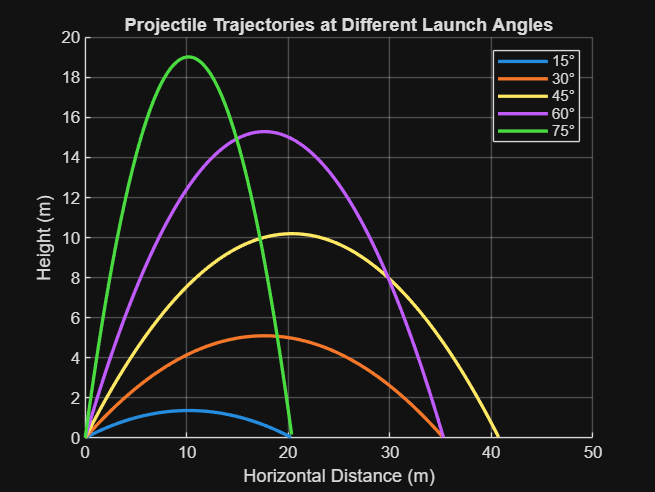



% The simulator now calculates three things about the projectile.
% Maximum height is found by looking at the exact point where the vertical
% velocity becomes zero before falling back down. 
% The flight time is just how long it takes to return back to ground level, 
% and the horizontal range is calculated by multiplying the horizontal speed by that total time.


% Launch angles to compare
angles = [15 30 45 60 75];

% Number of angles being tested
num_angles = length(angles);

% Create arrays to store the results
maximum_heights = zeros(1, num_angles);
flight_times = zeros(1, num_angles);
horizontal_ranges = zeros(1, num_angles);

% Create a new figure for the trajectory comparison
figure;
hold on;

% Repeat the calculation for each launch angle
for i = 1:num_angles

    % Select the current launch angle
    angle = angles(i);

    % Calculate horizontal and vertical velocity components
    vx = v0 * cosd(angle);
    vy = v0 * sind(angle);

    % Create enough time values to include all trajectories
    t = 0:0.01:5;

    % Calculate horizontal position
    x = v0 * cosd(angle) .* t;

    % Calculate vertical position
    y = h0 + v0 * sind(angle) .* t - 0.5 * g .* t.^2;

    % Keep only points at or above ground level
    valid = y >= 0;

    % Create filtered horizontal position values
    x_valid = x(valid);

    % Create filtered vertical position values
    y_valid = y(valid);

    % Plot the current trajectory
    plot(x_valid, y_valid, 'LineWidth', 2);

    % Calculate time to maximum height
    t_max_height = vy / g;

    % Calculate maximum height
    maximum_heights(i) = h0 + vy * t_max_height ...
        - 0.5 * g * t_max_height^2;

    % Calculate time of flight
    flight_times(i) = (2 * vy) / g;

    % Calculate horizontal range
    horizontal_ranges(i) = vx * flight_times(i);

end

% Finish the trajectory comparison graph
title('Projectile Trajectories at Different Launch Angles');
xlabel('Horizontal Distance (m)');
ylabel('Height (m)');
legend('15°', '30°', '45°', '60°', '75°');
grid on;
hold off;

% Save the graph as a PNG file
exportgraphics(gcf, 'trajectory_comparison.png', 'Resolution', 300); 


% Display a heading for the launch angle results
fprintf('\nLaunch Angle Results\n');


Launch Angle Results



% Repeat through each launch angle
for i = 1:num_angles

    % Display the angle, range, maximum height and flight time
    fprintf('Angle: %d° | Range: %.2f m | Maximum Height: %.2f m | Flight Time: %.2f s\n', ...
        angles(i), horizontal_ranges(i), maximum_heights(i), flight_times(i));

end

Angle: 15° | Range: 20.39 m | Maximum Height: 1.37 m | Flight Time: 1.06 s
Angle: 30° | Range: 35.31 m | Maximum Height: 5.10 m | Flight Time: 2.04 s
Angle: 45° | Range: 40.77 m | Maximum Height: 10.19 m | Flight Time: 2.88 s
Angle: 60° | Range: 35.31 m | Maximum Height: 15.29 m | Flight Time: 3.53 s
Angle: 75° | Range: 20.39 m | Maximum Height: 19.02 m | Flight Time: 3.94 s


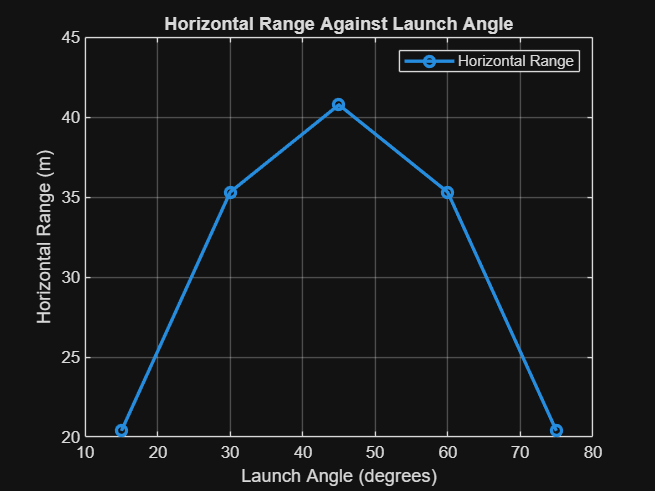



% Create a new figure
figure;

% Plot horizontal range against launch angle
plot(angles, horizontal_ranges, '-o', 'LineWidth', 2);

% Add a title to the graph
title('Horizontal Range Against Launch Angle');

% Label the horizontal axis
xlabel('Launch Angle (degrees)');

% Label the vertical axis
ylabel('Horizontal Range (m)');

% Add a legend
legend('Horizontal Range');

% Add a grid to make the graph easier to read
grid on;

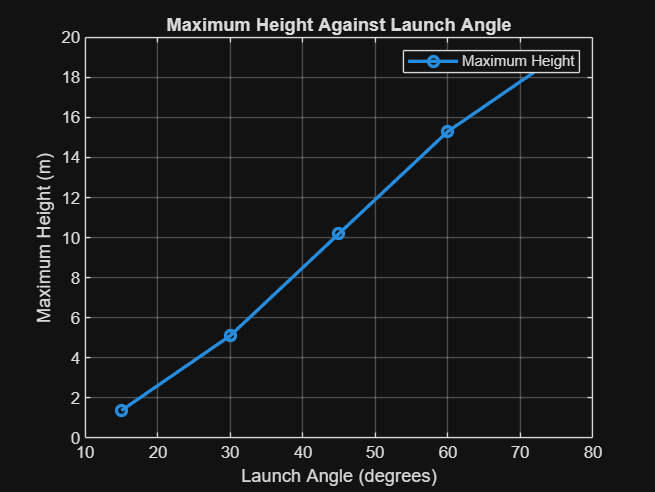




% Create a new figure
figure;

% Plot maximum height against launch angle
plot(angles, maximum_heights, '-o', 'LineWidth', 2);

% Add a title to the graph
title('Maximum Height Against Launch Angle');

% Label the horizontal axis
xlabel('Launch Angle (degrees)');

% Label the vertical axis
ylabel('Maximum Height (m)');

% Add a legend
legend('Maximum Height');

% Add a grid to make the graph easier to read
grid on;

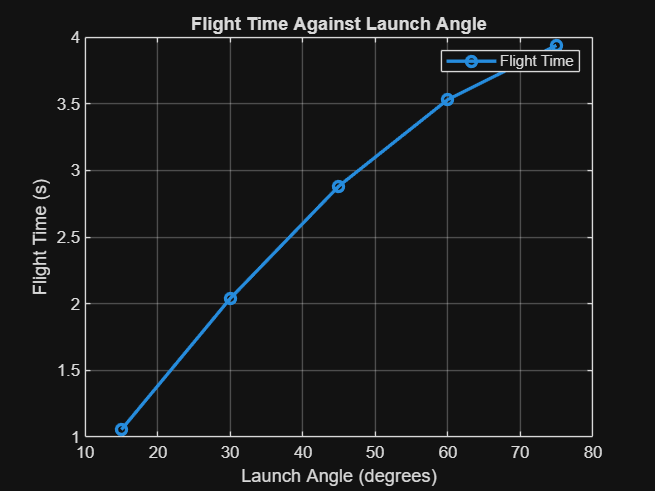



% Create a new figure
figure;

% Plot flight time against launch angle
plot(angles, flight_times, '-o', 'LineWidth', 2);

% Add a title to the graph
title('Flight Time Against Launch Angle');

% Label the horizontal axis
xlabel('Launch Angle (degrees)');

% Label the vertical axis
ylabel('Flight Time (s)');

% Add a legend
legend('Flight Time');

% Add a grid to make the graph easier to read
grid on;




% Find the greatest horizontal range
[max_range, max_index] = max(horizontal_ranges);

% Find the angle that produced the greatest range
best_angle = angles(max_index);

% Display the greatest range
fprintf('\nGreatest horizontal range: %.2f m\n', max_range);


Greatest horizontal range: 40.77 m



% Display the angle that produced the greatest range
fprintf('Angle producing greatest range: %d°\n', best_angle);

Angle producing greatest range: 45°


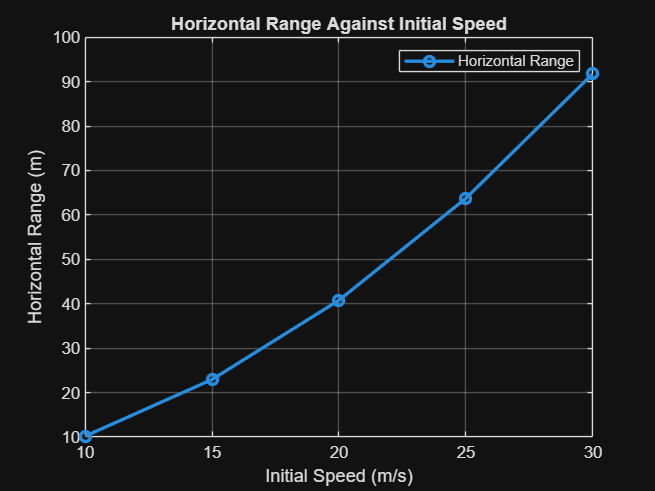




% Initial speeds to compare
speeds = [10 15 20 25 30];

% Keep the launch angle constant at 45 degrees
speed_angle = 45;

% Create arrays to store the speed comparison results
speed_ranges = zeros(1, length(speeds));
speed_heights = zeros(1, length(speeds));
speed_flight_times = zeros(1, length(speeds));

% Calculate results for each initial speed
for i = 1:length(speeds)

    % Select the current initial speed
    speed = speeds(i);

    % Calculate horizontal and vertical velocity components
    vx_speed = speed * cosd(speed_angle);
    vy_speed = speed * sind(speed_angle);

    % Calculate time to maximum height
    t_max = vy_speed / g;

    % Calculate maximum height
    speed_heights(i) = h0 + vy_speed * t_max ...
        - 0.5 * g * t_max^2;

    % Calculate flight time
    speed_flight_times(i) = (2 * vy_speed) / g;

    % Calculate horizontal range
    speed_ranges(i) = vx_speed * speed_flight_times(i);

end



% Create a new figure
figure;

% Plot horizontal range against initial speed
plot(speeds, speed_ranges, '-o', 'LineWidth', 2);

% Add a title to the graph
title('Horizontal Range Against Initial Speed');

% Label the horizontal axis
xlabel('Initial Speed (m/s)');

% Label the vertical axis
ylabel('Horizontal Range (m)');

% Add a legend
legend('Horizontal Range');

% Add a grid to make the graph easier to read
grid on;

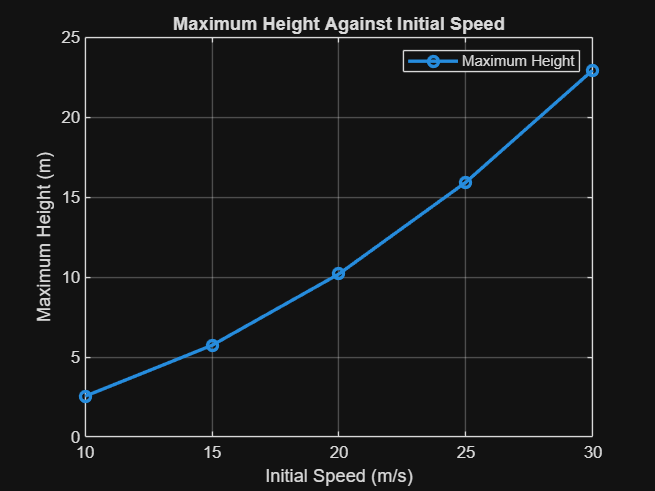




% Create a new figure
figure;

% Plot maximum height against initial speed
plot(speeds, speed_heights, '-o', 'LineWidth', 2);

% Add a title to the graph
title('Maximum Height Against Initial Speed');

% Label the horizontal axis
xlabel('Initial Speed (m/s)');

% Label the vertical axis
ylabel('Maximum Height (m)');

% Add a legend
legend('Maximum Height');

% Add a grid to make the graph easier to read
grid on;

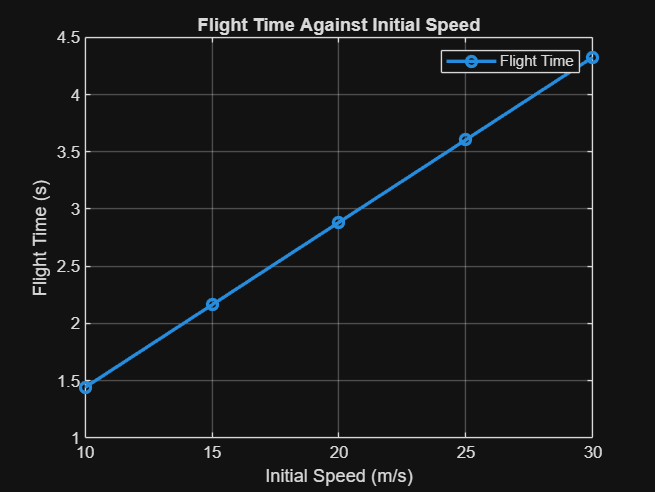



% Create a new figure
figure;

% Plot flight time against initial speed
plot(speeds, speed_flight_times, '-o', 'LineWidth', 2);

% Add a title to the graph
title('Flight Time Against Initial Speed');

% Label the horizontal axis
xlabel('Initial Speed (m/s)');

% Label the vertical axis
ylabel('Flight Time (s)');

% Add a legend
legend('Flight Time');

% Add a grid to make the graph easier to read
grid on;




% Display a heading for the initial speed results
fprintf('\nInitial Speed Results\n');


Initial Speed Results



% Repeat through each initial speed
for i = 1:length(speeds)

    % Display the speed, range, maximum height and flight time
    fprintf('Speed: %.0f m/s | Range: %.2f m | Maximum Height: %.2f m | Flight Time: %.2f s\n', ...
        speeds(i), speed_ranges(i), speed_heights(i), speed_flight_times(i));

end

Speed: 10 m/s | Range: 10.19 m | Maximum Height: 2.55 m | Flight Time: 1.44 s
Speed: 15 m/s | Range: 22.94 m | Maximum Height: 5.73 m | Flight Time: 2.16 s
Speed: 20 m/s | Range: 40.77 m | Maximum Height: 10.19 m | Flight Time: 2.88 s
Speed: 25 m/s | Range: 63.71 m | Maximum Height: 15.93 m | Flight Time: 3.60 s
Speed: 30 m/s | Range: 91.74 m | Maximum Height: 22.94 m | Flight Time: 4.32 s




% Analysis

% The trajectory graph shows that changing the launch angle changes the shape of the projectile's path.

% As the launch angle increases from 15 degrees to 45 degrees, the horizontal range increases.

% After 45 degrees, the horizontal range starts to decrease even though the maximum height continues to increase.

% This happens because increasing the angle gives the projectile more vertical velocity but less horizontal velocity.

% The 45 degree launch angle gives the greatest range in this test because the projectile starts and lands at the same height and air resistance is ignored.

% The 30 degree and 60 degree launches produce the same range because they are complementary angles.

% The same is true for the 15 degree and 75 degree launches.

% Maximum height increases as the launch angle increases because more of the initial velocity is directed vertically.

% Flight time also increases with launch angle because the projectile has a greater initial vertical velocity and therefore takes longer to return to the ground.

% The speed comparison shows that increasing the initial speed increases both the range and maximum height.

% For this model, range and maximum height are proportional to the square of the initial speed when the launch angle is kept constant.

% This means that increasing the speed from 10 m/s to 20 m/s makes the range and maximum height four times larger.

% Flight time is directly proportional to the initial speed when the launch angle stays at 45 degrees.

% Therefore, increasing the speed from 10 m/s to 30 m/s makes the flight time three times longer.

% These results support the main parts of my hypothesis.

% The model is simplified because it ignores air resistance and wind and treats the projectile as a single point.

% In real life, air resistance would slow the projectile down and would normally make the range different from the results predicted by this model.


% Conclusion

% This project showed me how launch angle and initial speed affect the motion of a projectile.

% From my results, 45 degrees gave the greatest horizontal range when the initial speed was 20 m/s and the projectile started and landed at the same height.

% The 30 degree and 60 degree launches gave the same range, as did the 15 degree and 75 degree launches.

% This happens because these pairs of angles are complementary and the range equation gives the same result for both angles.

% Increasing the launch angle increased the maximum height and flight time, but the range stopped increasing after 45 degrees.

% When I changed the initial speed while keeping the angle at 45 degrees, increasing the speed increased the range and maximum height by the square of the speed ratio.

% The flight time increased directly with the initial speed.

% I used physics equations for projectile motion and maths such as trigonometry to split the initial velocity into horizontal and vertical components.

% I also used MATLAB arrays, loops, calculations and graphs to make the testing quicker than calculating every result separately.

% One limitation is that the model ignores air resistance and wind, so it is not exactly how a real projectile would behave.

% If I developed the simulator further, I would add air resistance and possibly wind so that the model was closer to a real engineering situation.


% Check that the greatest range occurs at 45 degrees
if best_angle == 45
    fprintf('\nValidation passed: 45 degrees gives the greatest range.\n');
else
    fprintf('\nValidation warning: check the range calculations.\n');
end


Validation passed: 45 degrees gives the greatest range.



% Check the 30 and 60 degree ranges are approximately equal
if abs(horizontal_ranges(2) - horizontal_ranges(4)) < 0.01
    fprintf('Validation passed: 30 and 60 degrees give approximately the same range.\n');
else
    fprintf('Validation warning: check the complementary angle results.\n');
end

Validation passed: 30 and 60 degrees give approximately the same range.



% Check the 15 and 75 degree ranges are approximately equal
if abs(horizontal_ranges(1) - horizontal_ranges(5)) < 0.01
    fprintf('Validation passed: 15 and 75 degrees give approximately the same range.\n');
else
    fprintf('Validation warning: check the complementary angle results.\n');
end

Validation passed: 15 and 75 degrees give approximately the same range.



% Check that no plotted trajectory goes below ground level
if all(y_valid >= 0)
    fprintf('Validation passed: no plotted trajectory is below ground level.\n');
else
    fprintf('Validation warning: some trajectory values are below ground level.\n');
end

Validation passed: no plotted trajectory is below ground level.
